clear all; 

# Exercise 3.2 - Inverse Kinematic Algorithm

In this exercise you will setup an inverse kinematics algorithm using the pseudoinverse of the jacobian. 

Consider this UR3e robot: 

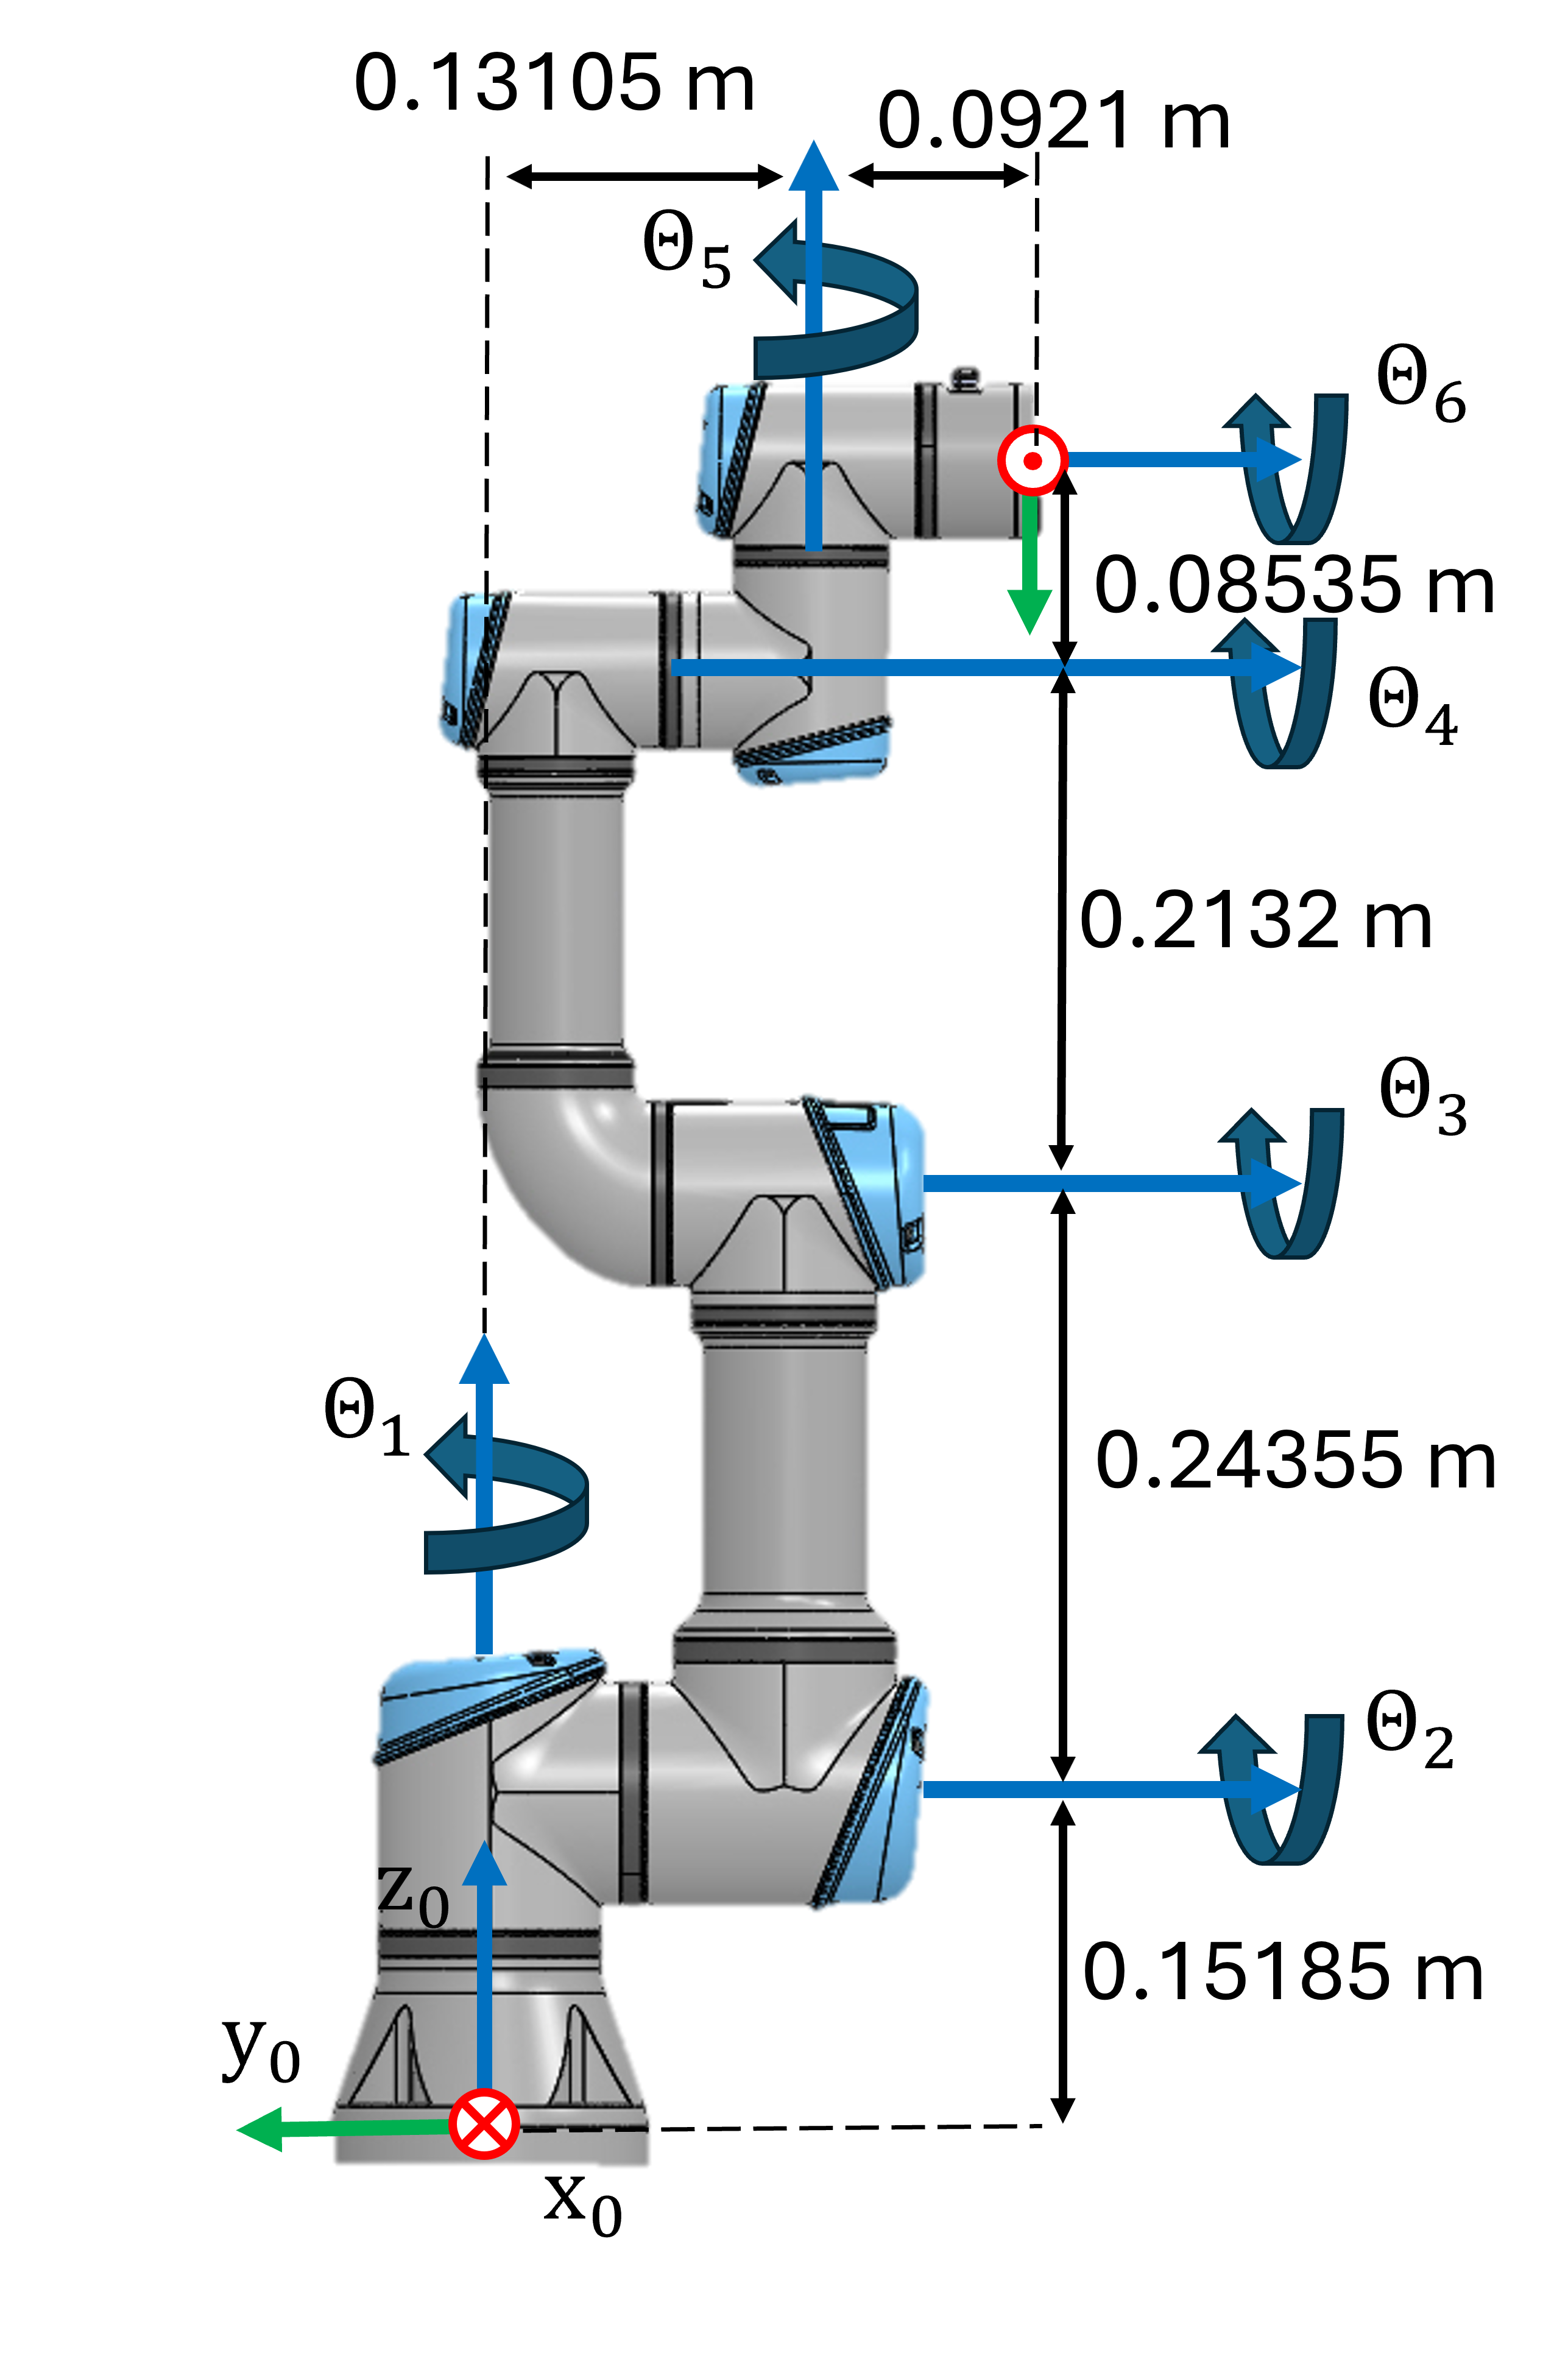

Consider this DH table for the UR3e: 

The control scheme you have to implement is: 

where $k\left(\cdot \right)$ is the forward kinematic of the q. 

## Task 1

Write a function that computes a solution to the inverse kinematic using the pseudoinverse of the Jacobian. The function has the following inputs: 

- the initial joint states as a row vector ($q_0 \in {\mathbb{R}}^{6\textrm{x1}}$)

- desired pose vector using euler angles (ZYZ) $x_{\textrm{desired}} =\left\lbrack \begin{array}{c}
x\\
y\\
z\\
\phi \\
\theta \\
\psi 
\end{array}\right\rbrack$

- gain (k) 

- tolerance (tol)

- max iterations (Imax)

The function should return the required joint states as a row vector ($q\in {\mathbb{R}}^{6\textrm{x1}}$)

For this task, consider $\dot{x_d } =\left\lbrack \begin{array}{c}
0\\
0\\
0\\
0\\
0\\
0
\end{array}\right\rbrack$ and $\Delta t=0\ldotp 01\;s$

Use the following function name for your solution:

-  PseudoInverseAlgorithm(q0, x_desired, k, tol, Imax)

You may use the function below to compute the symbolic transform from the base to the endeffector. 

- dh2tf()

Solve this exercise without using the function: 

- inverseKinematics()

function [q , x] = PseudoInverseAlgorithm(q0, x_desired, k, tol, Imax)


xdot_desired = [0;0;0;0;0;0];
dt = 0.01; 

syms q1 q2 q3 q4 q5 q6 real

q_syms = [q1,q2,q3,q4,q5,q6];

DH=[
    %a       alpha       d       theta
    0        pi/2        0.15185  q1;
    -0.24355 0           0       q2;
    -0.2132  0           0       q3;
    0        pi/2        0.13105 q4;
    0        -pi/2       0.08535 q5;
    0        0           0.0921  q6;
    ];

A06=dh2tf(DH);

p_ee = A06(1:3,4);

R_ee = A06(1:3,1:3);

phi = atan2(R_ee(2,3), R_ee(1,3));
theta = atan2(sqrt(R_ee(1,3)^2+R_ee(2,3)^2),R_ee(3,3));
psi = atan2(R_ee(3,2), -R_ee(3,1));

Jphi = [phi; theta; psi];


Jp = [];
J_phi_i = [];

for i=1:6
    Jp = [Jp, diff(p_ee, q_syms(i))];
    J_phi_i = [J_phi_i, diff(Jphi, q_syms(i))];
end

Ja_sym = simplify([J_phi_i; Jp]); 

x_sym = [p_ee; Jphi]; 
q = q0; 

i=0;

while i<Imax

Ja = double(subs(Ja_sym, q_syms, q'));
J_inv = pinv(Ja); 

x = double(subs(x_sym, q_syms, q'));
e = x_desired - x;


if mod(i, 100)==0
    x 
end


if norm(e) < tol
    break;
end

ekd = e * k + xdot_desired; 


q_dot = J_inv * ekd; 
q = q + q_dot * dt; 
q = mod(q + pi, 2*pi) - pi;
    i = i + 1;
end

end


You can check your work by clicking the Run: 

Error using fileread (line 10)
Could not open file exercises/exercise-3-2-1.json. No such file or directory.

Error in check_exercise (line 8)
    data = jsondecode( fileread(json_file) );
    ^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^

check_exercise('3-2-1')

% Initialize the time tracking and iteration counting
start_time = tic; 
total_iterations = 0;

q0 = [pi/3,-pi/6, pi/3.5,pi/3,-pi/6, pi/3.5]'; 
x_desired = [0.3, 0.3, 0.3, 0, 0, 0]'; 
k = 1; 
tol = 1e-3;
Imax = 1000; 
% Call the PseudoInverseAlgorithm to compute joint angles
[q, x_out] = PseudoInverseAlgorithm(q0, x_desired, k, tol, Imax)

x =     0.0235
   -0.3809
    0.2285
   -0.4378
    1.0536
   -2.4163


x =     0.0230
   -0.3817
    0.2292
   -0.1690
    1.7376
   -2.3429


x =     0.0228
   -0.3818
    0.2293
    0.1054
    2.4210
   -2.2716


x =     0.0227
   -0.3818
    0.2295
    0.3848
    3.1030
   -2.1976


x =     0.0228
   -0.3818
    0.2297
   -2.9612
    3.1392
    0.5338


x =     0.0228
   -0.3818
    0.2300
    3.0988
    3.1392
    0.1043


x =     0.0228
   -0.3819
    0.2302
    2.8817
    3.1392
   -0.3198


total_time = toc(start_time)
solution_error = x_desired - x_out

## Task 2

Extend your function from before. 

Add the input: 

- dt (time for discrete algorithm step)

Add the outputs: 

- total_time (time it takes for the algorithm to find a solution)

- total_iterations (iterations until the solution was found)

- solution_error (the pose square error for the solution configuration$\left({\textrm{error}}_{\textrm{solution}} \left(q\right)={e\left(q\right)}^T \cdot e\left(q\right)\right)$)

Use "tic" and "toc" to measure the compuational time. 

Use the following function name for your solution:

-  ExtendedPseudoInverseAlgorithm(t_desired, k, dt, tol, Imax)

Solve this exercise without using the function: 

- inverseKinematics()

function [q,total_time,total_iterations,solution_error] = ExtendedPseudoInverseAlgorithm(t_desired, k, dt, tol, Imax)

tic; 
xdot_desired = [0;0;0;0;0;0];

syms q1 q2 q3 q4 q5 q6 real

q_syms = [q1,q2,q3,q4,q5,q6];

DH=[
    %a       alpha       d       theta
    0        pi/2        0.15185  q1;
    -0.24355 0           0       q2;
    -0.2132  0           0       q3;
    0        pi/2        0.13105 q4;
    0        -pi/2       0.08535 q5;
    0        0           0.0921  q6;
    ];

A06=dh2tf(DH);

p_ee = A06(1:3,4);

R_ee = A06(1:3,1:3);

phi = atan2(R_ee(2,3), R_ee(1,3));
theta = atan2(sqrt(R_ee(1,3)^2+R_ee(2,3)^2),R_ee(3,3));
psi = atan2(R_ee(3,2), -R_ee(3,1));

Jphi = [phi; theta; psi];


Jp = [];
J_phi_i = [];

for i=1:6
    Jp = [Jp, diff(p_ee, q_syms(i))];
    J_phi_i = [J_phi_i, diff(Jphi, q_syms(i))];
end

Ja_sym = simplify([J_phi_i; Jp]); 

x_sym = [p_ee; Jphi]; 
q = q0; 

i=0;

while i<Imax

Ja = double(subs(Ja_sym, q_syms, q'));
J_inv = pinv(Ja); 

x = double(subs(x_sym, q_syms, q'));
e = x_desired - x;


if mod(i, 100)==0
    x 
end


if norm(e) < tol
    break;
end

ekd = e * k + xdot_desired; 


q_dot = J_inv * ekd; 
q = q + q_dot * dt; 
q = mod(q + pi, 2*pi) - pi;
    i = i + 1;
end

total_iterations = i;
total_time = toc; 
solution_error = e'*e; 

end




Analyze how your algorithm behaves when you change the tolerance, gain or timestep. 